clear; clc;
% Experimental Data (Replace with actual values)
m_tot_data = [0.05, 0.025, 0.0125, 0.005, 0.0025, 0.00125, 0.000625];  % Total concentration (M)
observed_shifts = [7.2341, 7.2271, 7.2236, 7.222, 7.2214, 7.2209, 7.2208];  % NMR chemical shifts

% Initial parameter guesses: [K1, K2, delta_M, delta_M2, delta_M3]
initial_guess = [1, 100, 7.22, 7.23, 7.3];

% Use lsqcurvefit to fit the model
options = optimset('Display', 'iter', 'TolFun', 1e-6, 'TolX', 1e-6);
fitted_params = lsqcurvefit(@(params, m_tot) trimer_equilibrium(params, m_tot), ...
initial_guess, m_tot_data, observed_shifts, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6        7.4336e-06                           0.0029
     1         12       5.41868e-06              10         0.000269      
     2         18       3.99171e-06              20         0.000222      
     3         24       2.45107e-06              40          0.00188      
     4         30       2.41793e-06              80          0.00287      
     5         36       1.15583e-06              20          0.00012      
     6         42       1.15583e-06              40          0.00012      
     7         48       1.14842e-06              10         0.000208      
     8         54       1.14301e-06              10          0.00012      
     9         60       1.13787e-06              10         0.000161      
    10         66       1.13392e-06              10          0.00012      
    11         72       1.12938e-06      


% Display fitted parameters
fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K1 = %.2f\n', fitted_params(1));

K1 = 0.14


fprintf('K2 = %.2f\n', fitted_params(2));

K2 = 440.00


fprintf('δ_M = %.4f\n', fitted_params(3));

δ_M = 7.2213


fprintf('δ_M2 = %.4f\n', fitted_params(4));

δ_M2 = 7.3568


fprintf('δ_M3 = %.4f\n', fitted_params(5));

δ_M3 = 7.2858



% Compute fitted shifts and species concentrations
[fitted_shifts, M, M2, M3] = trimer_equilibrium(fitted_params, m_tot_data);

% Calculate species fractions
total_species = M + 2*M2 + 3*M3;
frac_M = M ./ total_species;
frac_M2 = 2*M2 ./ total_species;
frac_M3 = 3*M3 ./ total_species;
abs_error = abs(fitted_shifts - observed_shifts);

% Create summary table
summaryTable = table(...
    m_tot_data'*1000, observed_shifts', fitted_shifts', abs_error', ...
    frac_M', frac_M2', frac_M3', ...
    'VariableNames', {'[M]_{tot} (mM)', 'δ_obs', 'δ_fit', 'Abs_Error', ...
                      'Frac_M', 'Frac_Dimer', 'Frac_Trimer'});
disp(' ');

disp('=== Summary Table ===');

=== Summary Table ===


disp(summaryTable);

    [M]_{tot} (mM)    δ_obs     δ_fit     Abs_Error     Frac_M     Frac_Dimer    Frac_Trimer
    ______________    ______    ______    __________    _______    __________    ___________

           50         7.2341    7.2334    0.00067774    0.81993     0.0076543       0.17242 
           25         7.2271    7.2273    0.00021122    0.91232     0.0055718      0.082109 
         12.5         7.2236    7.2234    0.00024607    0.97104     0.0032183      0.025737 
            5          7.222    7.2217    0.00027386    0.99421     0.0013518     0.0044347 
          2.5         7.2214    7.2214    2.1496e-05     0.9982    0.00068135     0.0011222 
         1.25         7.2209    7.2213    0.00042119    0.99938    0.00034148    0.00028154 
        0.625         7.2208    7.2213    0.00048445    0.99976    0.00017087    7.0467e-05 



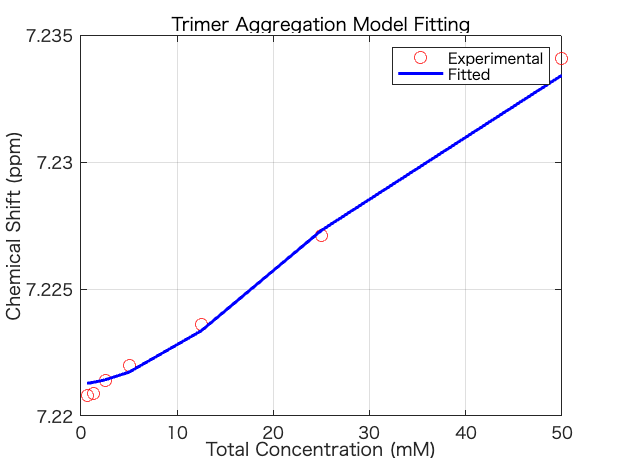


% Plot
figure;
plot(m_tot_data*1000, observed_shifts, 'ro', 'MarkerSize', 8, 'DisplayName', 'Experimental');
hold on;
plot(m_tot_data*1000, fitted_shifts, 'b-', 'LineWidth', 2, 'DisplayName', 'Fitted');
xlabel('Total Concentration (mM)');
ylabel('Chemical Shift (ppm)');
title('Trimer Aggregation Model Fitting');
legend;
grid on;


% R-squared
SS_res = sum((observed_shifts - fitted_shifts).^2);
SS_tot = sum((observed_shifts - mean(observed_shifts)).^2);
R_squared = 1 - SS_res / SS_tot;
fprintf('R-squared: %.4f\n', R_squared);

R-squared: 0.9926



function [delta_obs, M, M2, M3] = trimer_equilibrium(params, m_tot)
    K1 = params(1);
    K2 = params(2);
    delta_M = params(3);
    delta_M2 = params(4);
    delta_M3 = params(5);

    % Approximate monomer concentration
    M = m_tot ./ (1 + 2*K1*m_tot + 3*K1*K2*m_tot.^2);
    M2 = K1 * M.^2;
    M3 = K2 * M .* M2;

    % Observed chemical shift
    delta_obs = (M .* delta_M + 2*M2 .* delta_M2 + 3*M3 .* delta_M3) ./ (M + 2*M2 + 3*M3);
end
